# 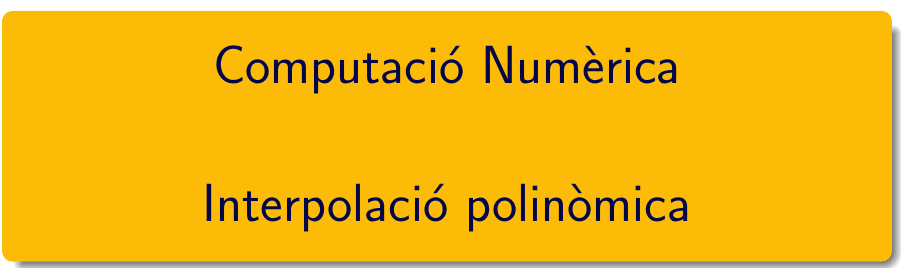

================================================================================

# Pràctica 6 - Interpolació polinònimca i ajust de dades (I)

`document preparat per M. Àngela Grau Gotés - març 2023`

## $\bullet$APRENEM .....Bloc1

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

- avalueu el polinomi  $x^5-1$ per $x=2$

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

% x^3 + 4*x^2 + 4*x = 0

p =      1     4     4     0


arrels =      0
    -2
    -2


p = [1 4 4 0], arrels = roots(p)    % vector amb els coeficients del polinomi i arrels
% x^5 - 1

p =      1     0     0     0     0    -1


p = [1 0 0 0 0 -1] % vector amb els coeficients del polinomi 

ans = 31

polyval(p, 2)      % valor polinomi en x = 2

r =     -5    -2    -1     1     2     8


r = [-5 -2 -1 1 2 8] % vector amb les arrels

p =      1    -3   -45    15   204   -12  -160


p = poly(r)        % coeficients polinomi d'arrels r

ans =     8.0000
   -5.0000
    2.0000
    1.0000
   -2.0000
   -1.0000


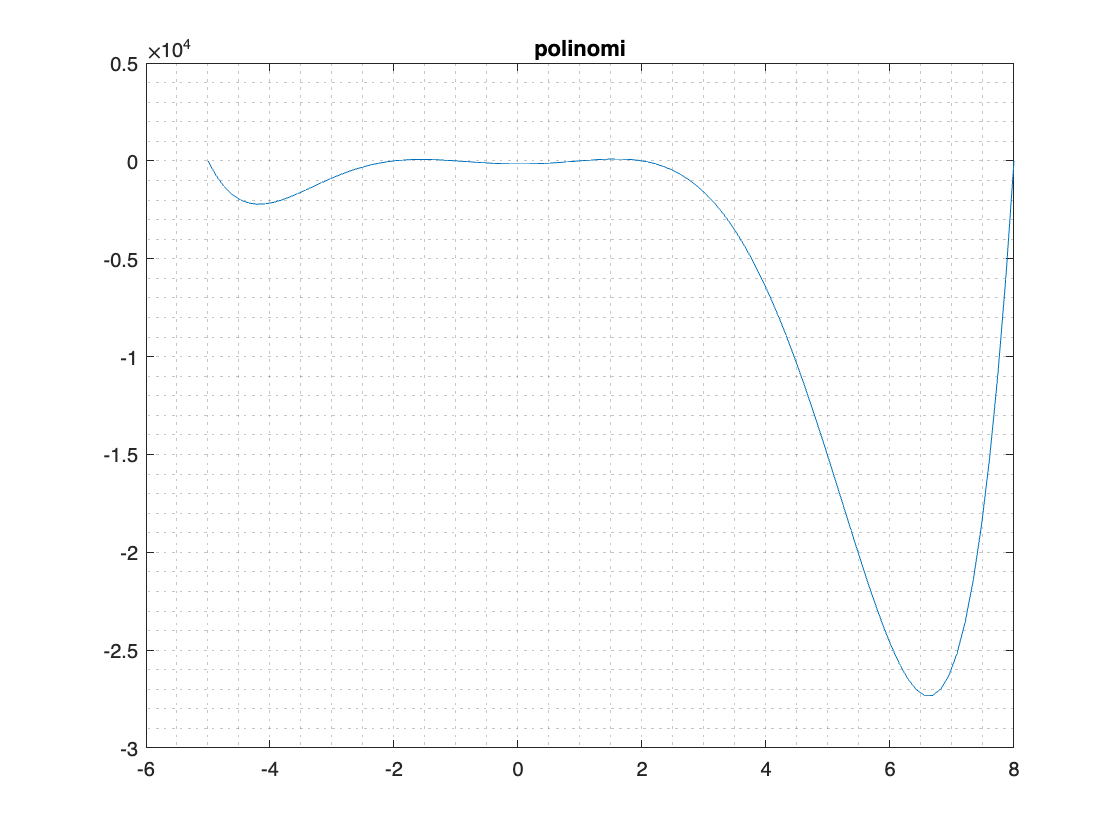

roots(p)
t = linspace(min(r), max(r));
pt = polyval(p, t);

plot(t, pt), title('polinomi'), grid minor

### Polinomi interpolador (matriu de Vandermonde)

Els coeficients del polinomi interpolador s'obtenen resolent el sistema lineal corresponent: amb matriu del sistema la matriu de Vandermonde.

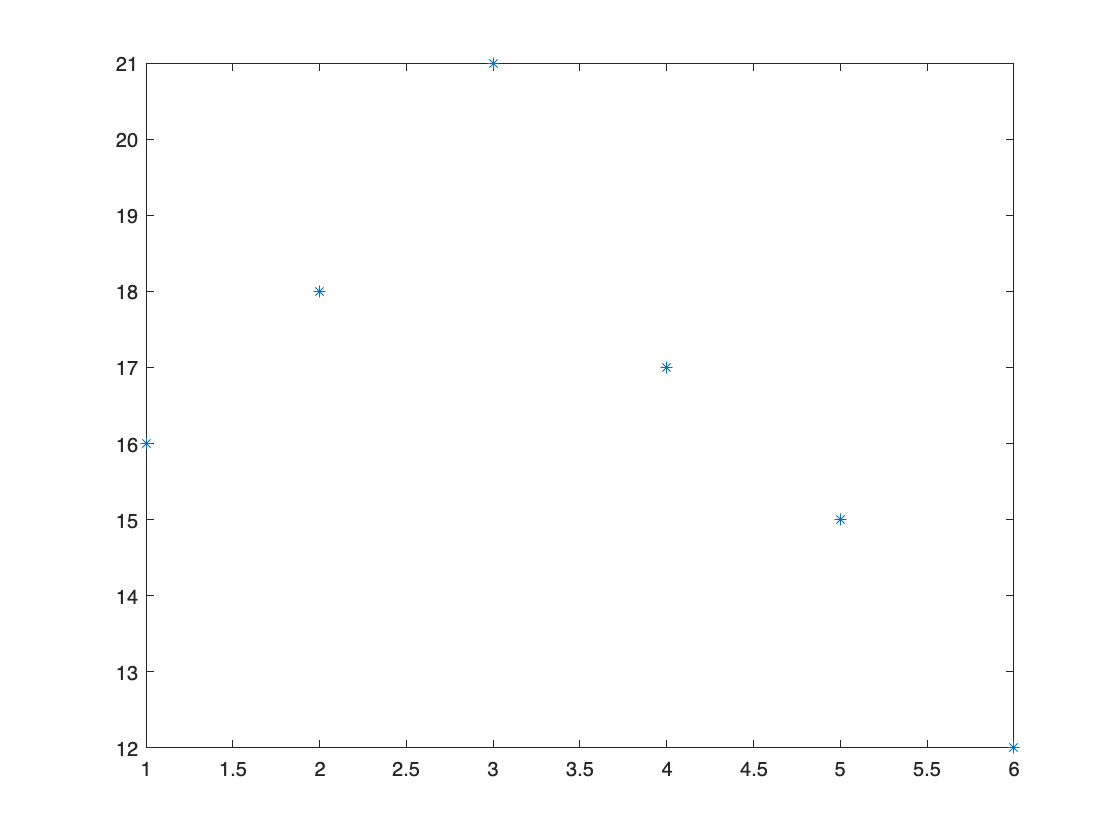

x = 1:6;
y = [16 18 21 17 15 12];    

plot(x,y,'*')

V =            1           1           1           1           1           1
          32          16           8           4           2           1
         243          81          27           9           3           1
        1024         256          64          16           4           1
        3125         625         125          25           5           1
        7776        1296         216          36           6           1


V = vander(x)

c =    -0.2417
    4.3333
  -28.9583
   87.6667
 -115.8000
   69.0000


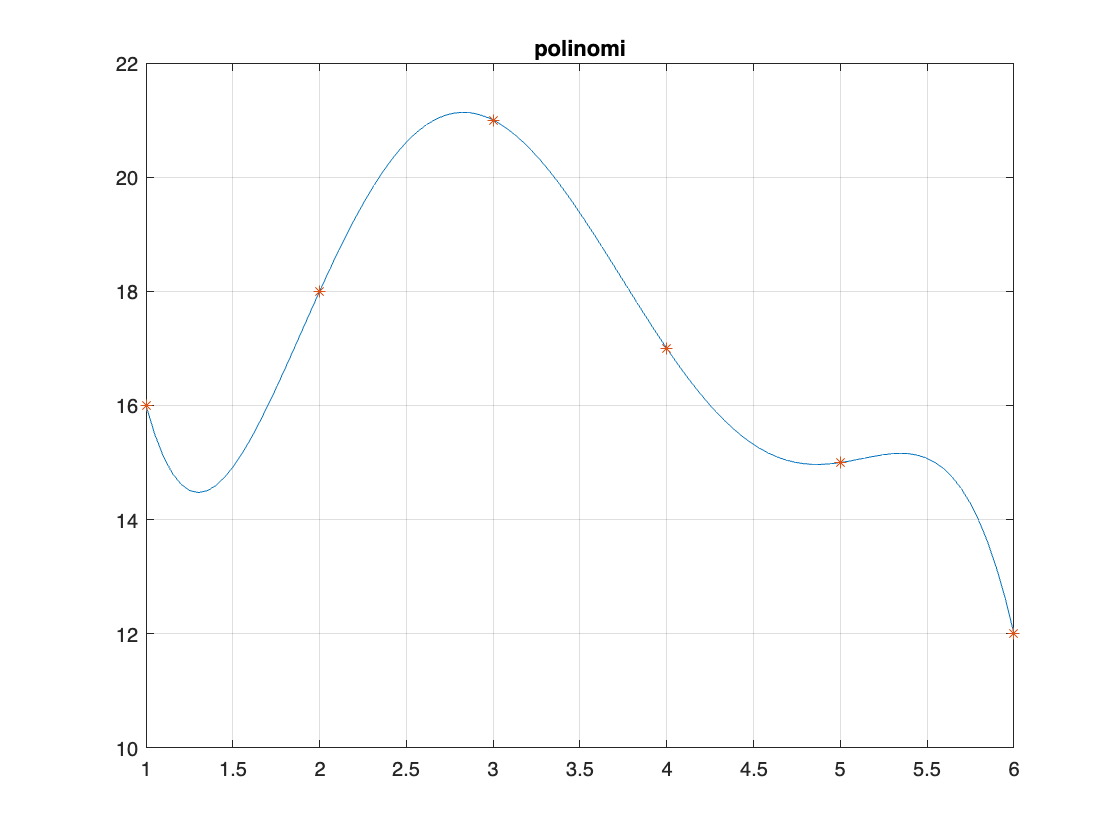

c = linsolve(V,y')
t = linspace(1, 6);
pt = polyval(c, t);

plot(t, pt, x, y, '*'), title('polinomi'), grid

### Polinomi interpolador (fórmula de Lagrange)

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"*[*Numerical Computing with Matlab*](https://www.mathworks.com/moler/chapters.html)*". *

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

`Exemple 1`` - Llista de problemes, exercici 1`. 

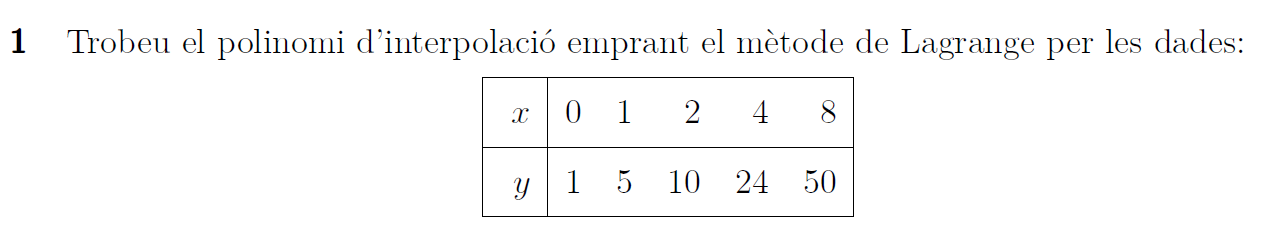

x = [0, 1, 2, 4, 8];
y = [1, 5, 10, 24, 50];

ans = 16.3616

polyinterp(x,y,3) % para el punto x = 3

t =          0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788    3.9596


pt =     1.0000    1.3024    1.6069    1.9139    2.2239    2.5375    2.8550    3.1770    3.5038    3.8358    4.1735    4.5171    4.8671    5.2237    5.5873    5.9581    6.3364    6.7226    7.1167    7.5190    7.9297    8.3490    8.7770    9.2138    9.6597   10.1146   10.5786   11.0519   11.5344   12.0262   12.5273   13.0376   13.5571   14.0858   14.6236   15.1704   15.7260   16.2904   16.8635   17.4449   18.0346   18.6323   19.2378   19.8509   20.4712   21.0986   21.7327   22.3732   23.0197   23.6719


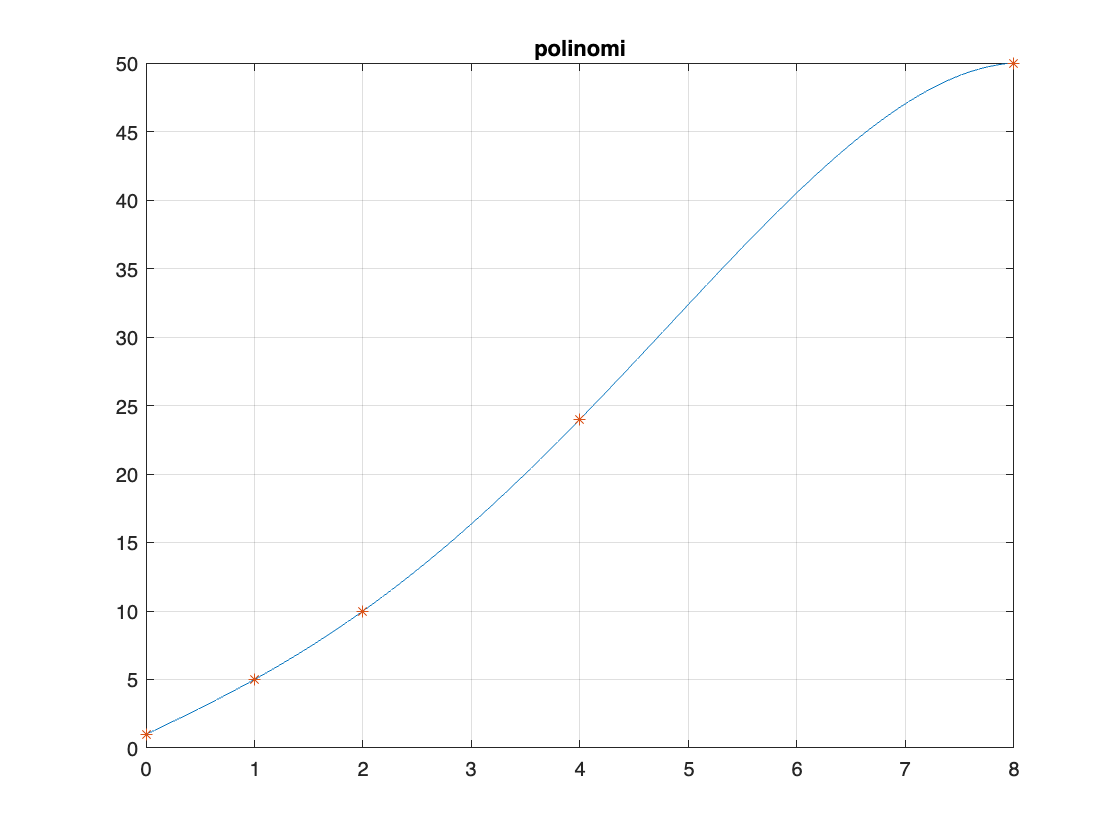

t = linspace(0, 8), pt = polyinterp(x,y,t)

plot(t, pt, x, y, '*'), title('polinomi'), grid
syms X p(X)

$$p(X) = \left(\frac{X}{2}-1\right)\,\left(\frac{X}{4}-1\right)\,\left(\frac{X}{8}-1\right)\,\left(X-1\right)+5\,X\,\left(\frac{X}{2}-2\right)\,\left(\frac{X}{6}-\frac{4}{3}\right)\,\left(X-1\right)-5\,X\,\left(\frac{X}{3}-\frac{4}{3}\right)\,\left(\frac{X}{7}-\frac{8}{7}\right)\,\left(X-2\right)-6\,X\,\left(\frac{X}{2}-1\right)\,\left(\frac{X}{4}-2\right)\,\left(\frac{X}{3}-\frac{1}{3}\right)+\frac{25\,X\,\left(\frac{X}{4}-1\right)\,\left(\frac{X}{6}-\frac{1}{3}\right)\,\left(\frac{X}{7}-\frac{1}{7}\right)}{4}$$

p(X) = polyinterp(x,y,X)

$$p(X) = -\frac{25\,X^{4}}{1344}+\frac{11\,X^{3}}{64}+\frac{11\,X^{2}}{96}+\frac{209\,X}{56}+1$$

p(X) = simplify(p(X))

$$V = \frac{3665}{224}$$

$$ans = 16.361607142857142857142857142857$$

V = p(3), vpa(V)

### Polinomi interpolador (diferències dividides de Newton)

`Exemple 2`` - Llista de problemes, exercici 2`. 

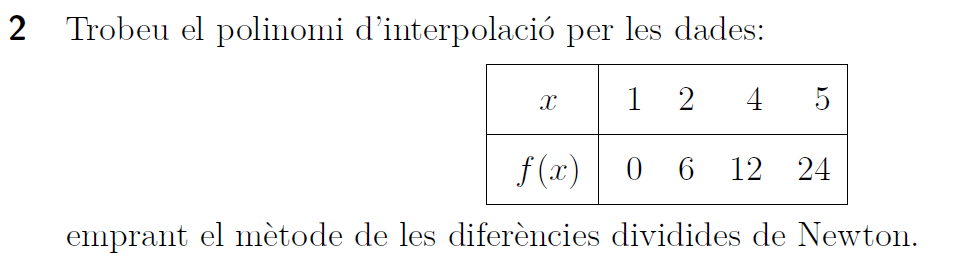

Baixeu-vos el codi de MATLAB fileEchange [codi diferències dividides](https://es.mathworks.com/matlabcentral/fileexchange/105325-matlab-functions-for-numerical-interpolation-methods)

clearvars
x = [1 2 4 5];
y = [0 6 12 24];


     1     0     6    -1     1
     2     6     3     3     0
     4    12    12     0     0
     5    24     0     0     0



[ sol ] = fNewtonDDI( x,y,[3,4] ); % punts x = 3 i x = 4

n = 4

c =     1.0000   -8.0000   23.0000  -16.0000


n = length(x), c = polyfit(x,y,n-1)

ans =     8.0000   12.0000


polyval(c, [3,4])

### Funció de MATLAB®

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

`Exemple 3`` - Canvi d'escala` 

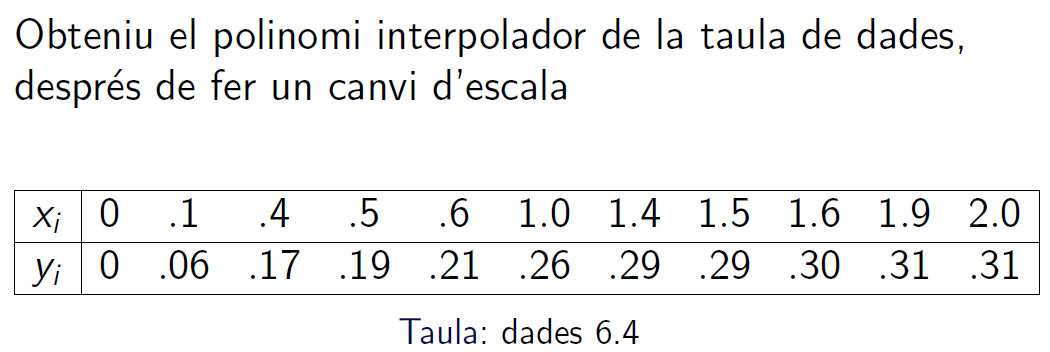

x = [0 .1 .4 .5 .6 1.0 1.4 1.5 1.6 1.9 2.0];
y = [0 .06 .17 .19 .21 .26 .29 .29 .30 .31 .31];

n = 11

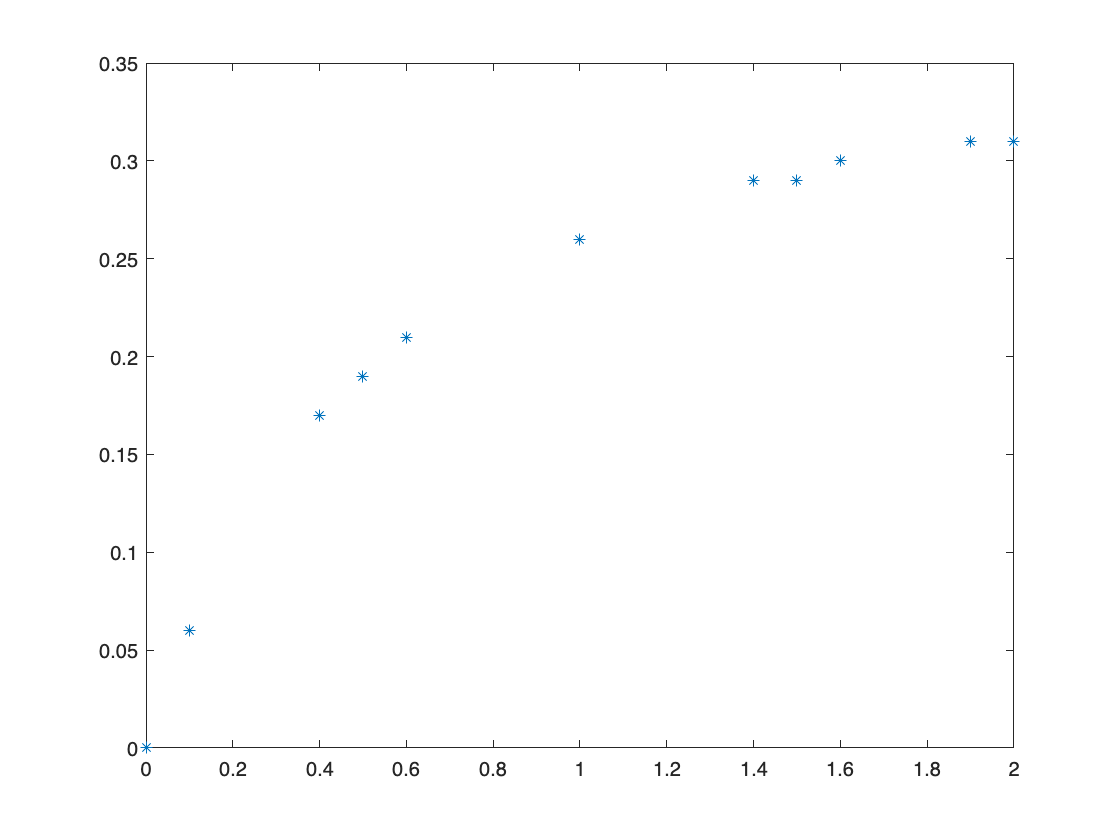

n = length(x)

plot(x,y,'*')

ans = 1

ans = 0.7183

mean(x), std(x)

c =     3.5249  -34.4651  143.3588 -330.9524  463.8136 -405.1516  217.2894  -66.9804    9.7048    0.1182   -0.0000


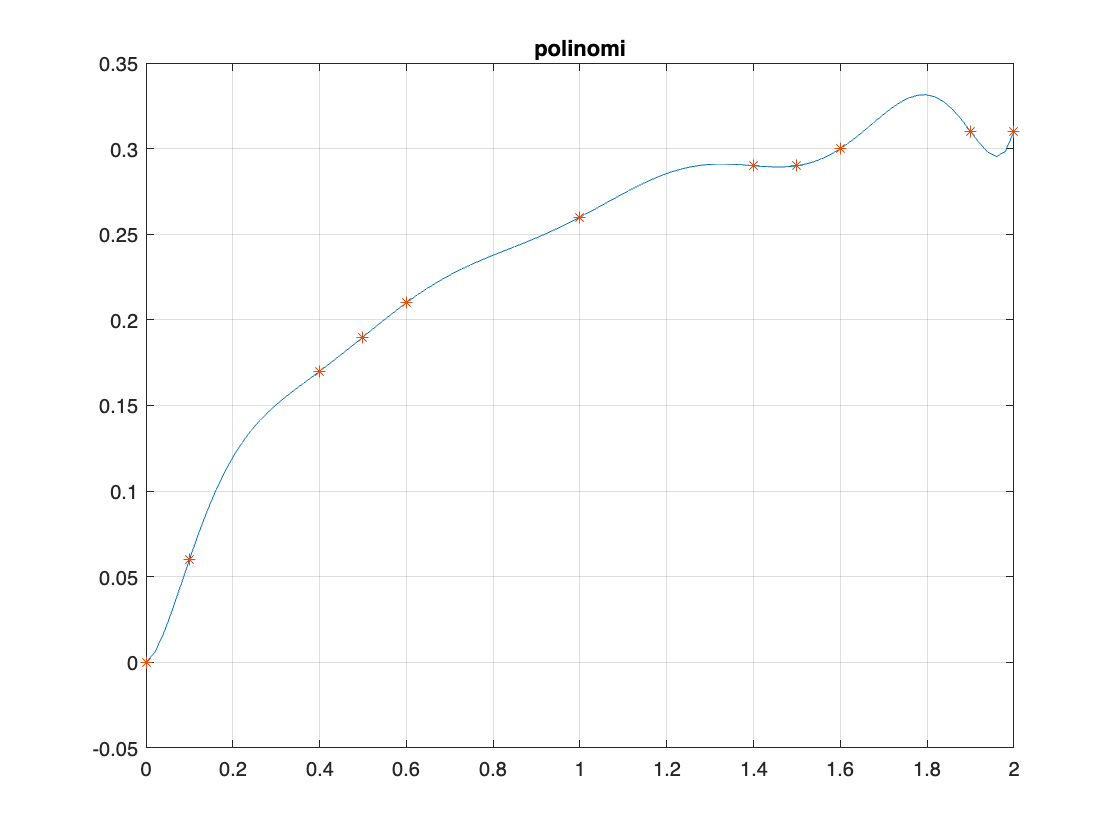

c = polyfit(x, y, n-1)
t = linspace(0, 2);
pt = polyval(c, t);

plot(t, pt, x, y, '*'), title('polinomi'), grid

`OBSERVACIÓ - polyinterp de Moler = polyfit + polyval de MATLAB`

## $\bullet$PRACTIQUEM ....

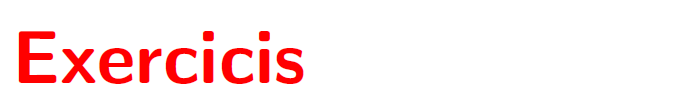

### Exercici 1

Aquest exercici s'ha de resoldre fent ús de polinomis de Lagrange,  **polyinterp**

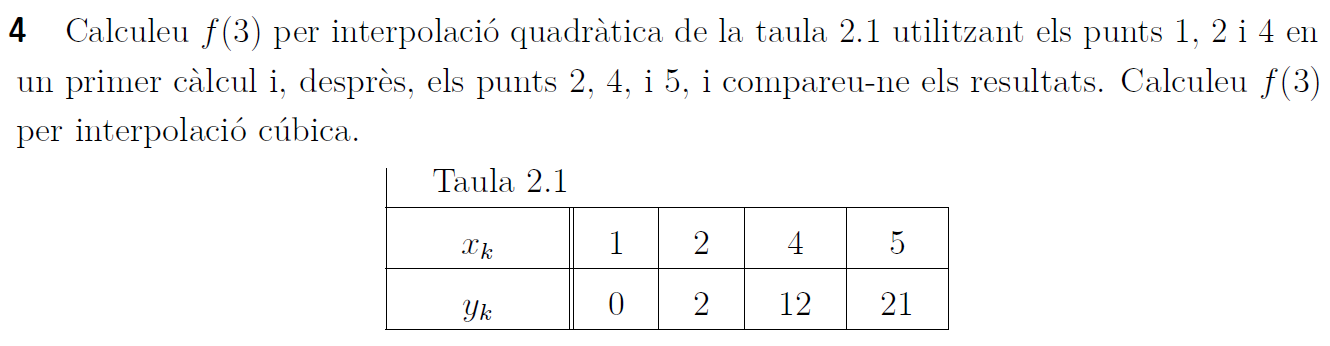

clearvars
x = [1 2 4 5]; y = [0 2 12 21];

x1 =      1     2     4


y1 =      0     2    12


- primer càlcul

x1 = x(1:3),  y1 = y(1:3)
valor = polyinterp(x1,y1,3);

valor1 = 6


disp(['valor1 = ',num2str(valor)])

x2 =      2     4     5


y2 =      2    12    21


- segon  càlcul

 x2 = x(2:4), y2 = y(2:4)
valor2 = polyinterp(x2,y2,3);

valor2 = 5.6667


disp(['valor2 = ',num2str(valor2)])

- tercer  càlcul

### Exercici 2

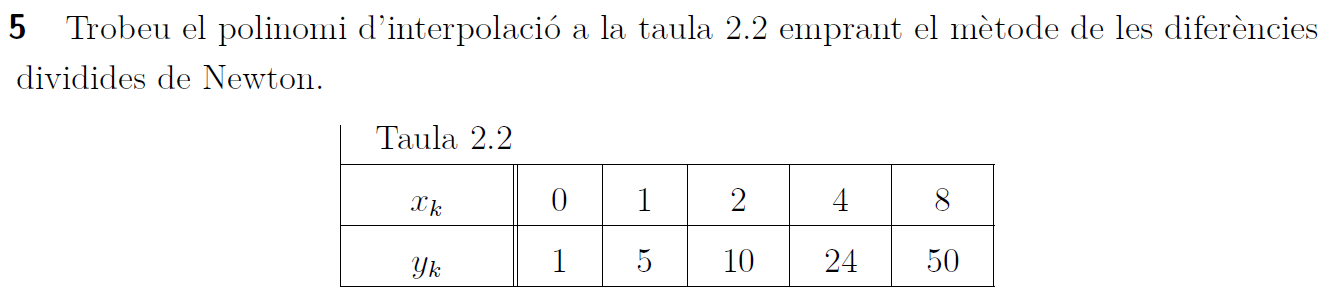

clearvars; clf
x = [0 1 2 4 8]; y = [0,5 10 24 50];

     0     1     2     4     8
     0     5    10    24    50



disp([x; y])
 

### Exercici 3

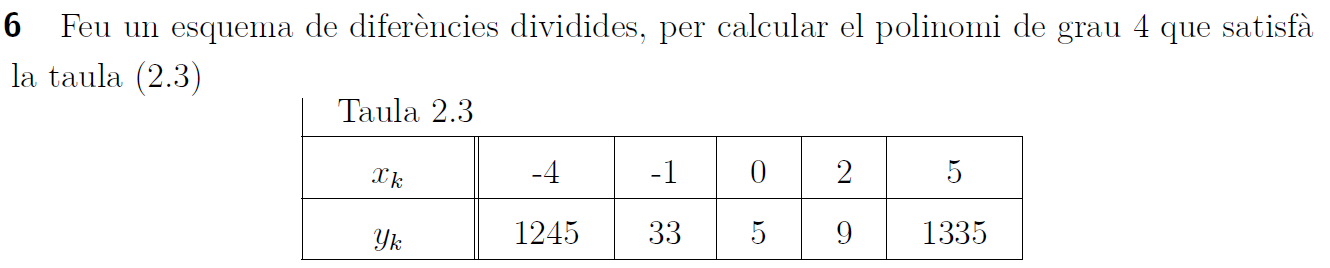

clearvars; clf
x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];

          -4          -1           0           2           5
        1245          33           5           9        1335



disp([x; y])

alpha = -3.5565

tolf = -38.5958

### Exercici 4. Interpolació inversa

Aplicació de la interpolació al càlcul de zeros de funcions (`Interpolació inversa`)

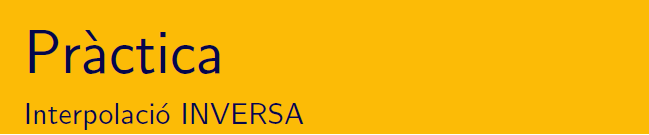

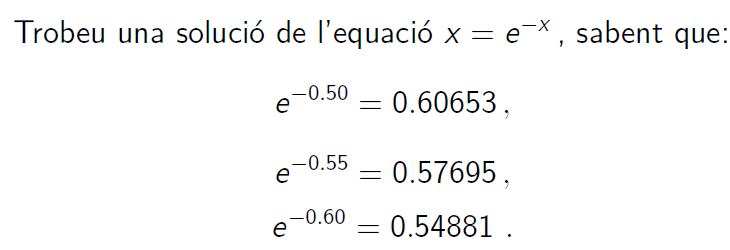


x = [0.5:0.05:0.6];
y = x-exp(-x);

    0.5000   -0.1065
    0.5500   -0.0269
    0.6000    0.0512



disp([x; y]')

alpha = 0.5671

alpha = polyinterp(y,x,0)

tolf = 3.3969e-07

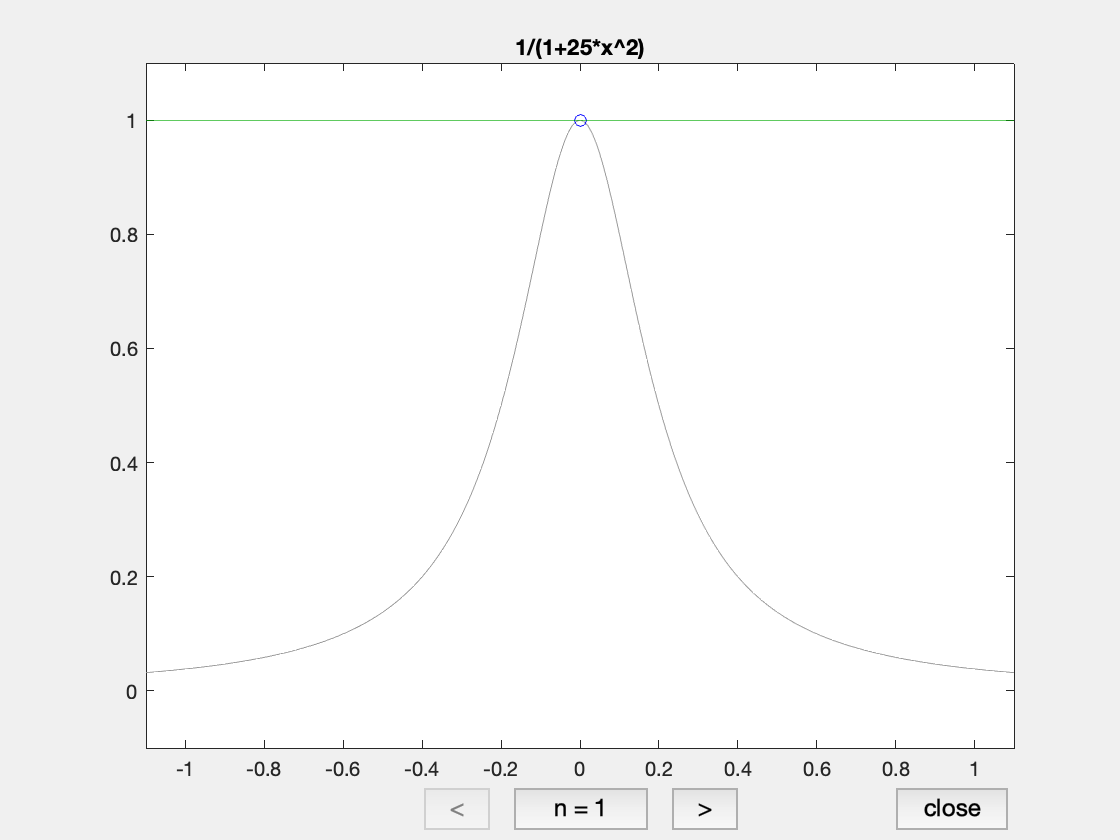

tolf = alpha - exp(-alpha)

### Exercici 5. Comportament de l'error en la interpolació polinòmica

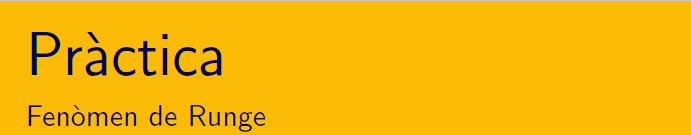

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. Enllaç blog Cleve Moler [Explore Runge’s Polynomial Interpolation Phenomenon](https://blogs.mathworks.com/cleve/2018/12/10/explore-runges-polynomial-interpolation-phenomenon/)

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

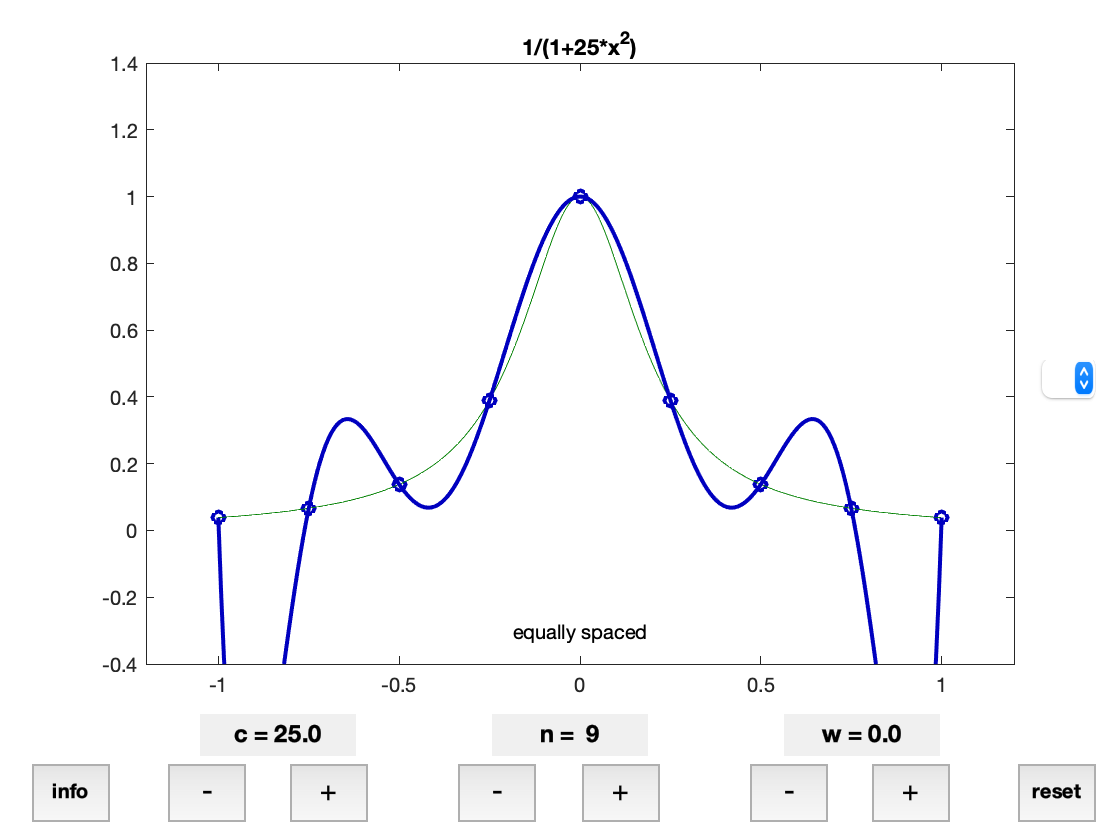

interp_gadget()

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

## $\bullet$APRENEM ..... Bloc 2

### Interpolació polinomial a trossos. 

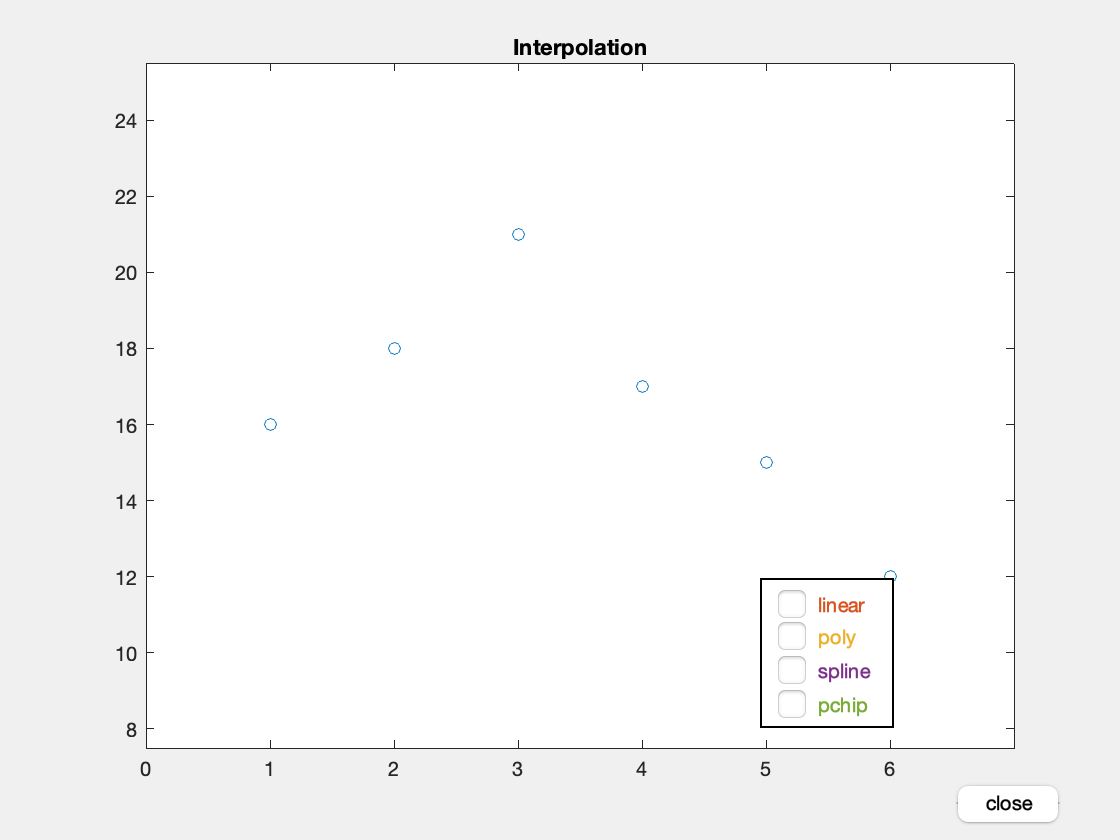

clearvars; 
x = 1:6;
y = [16 18 21 17 15 12];
interpgui(x,y)

**Diferències entre spline i pchip**

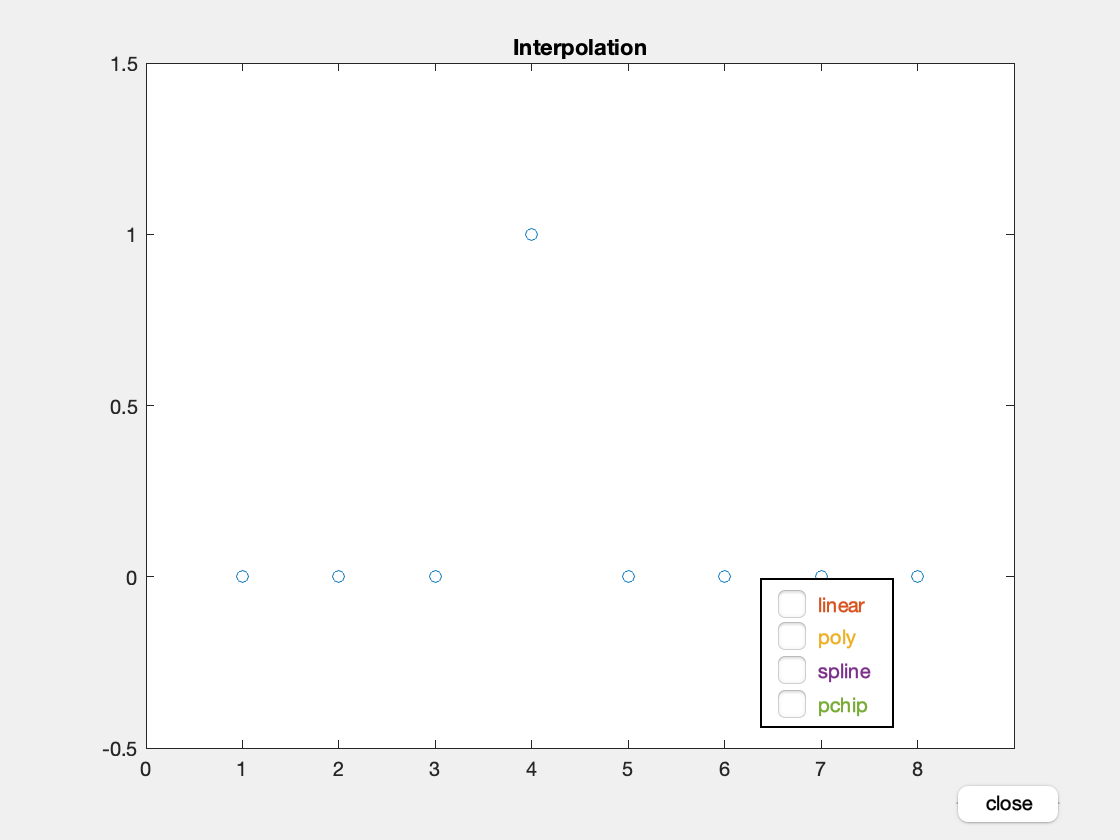

clearvars;
x = 1: 8;
y = zeros (1,8);
y (4) = 1;
interpgui(x, y)

### Funció de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

Baixeu-vos del campus ***InterpolationofCoarselySampledSineFunctionExample.mlx, ***és el primer exemple de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline lineal i els valors de l'spline cúbic. 

% openExample('matlab/InterpolationofCoarselySampledSineFunctionExample')

**INTERPOLACIÓ I EXTRAPOLACIÓ**

Baixeu-vos del campus ***ExtrapolationUsingTwoDifferentMethodsExample.mlx*** . Aquest codi és de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline per avaluar punts que es troben fora del domini de x.

% openExample('matlab/ExtrapolationUsingTwoDifferentMethodsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 6

Per la taula de dades següent es demana la representació gràfica :

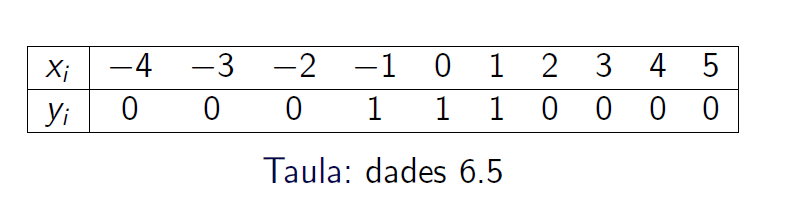

x = -4:5; y = [0 0 0 1 1 1 0 0 0 0];
disp([x; y])

    -4    -3    -2    -1     0     1     2     3     4     5
     0     0     0     1     1     1     0     0     0     0



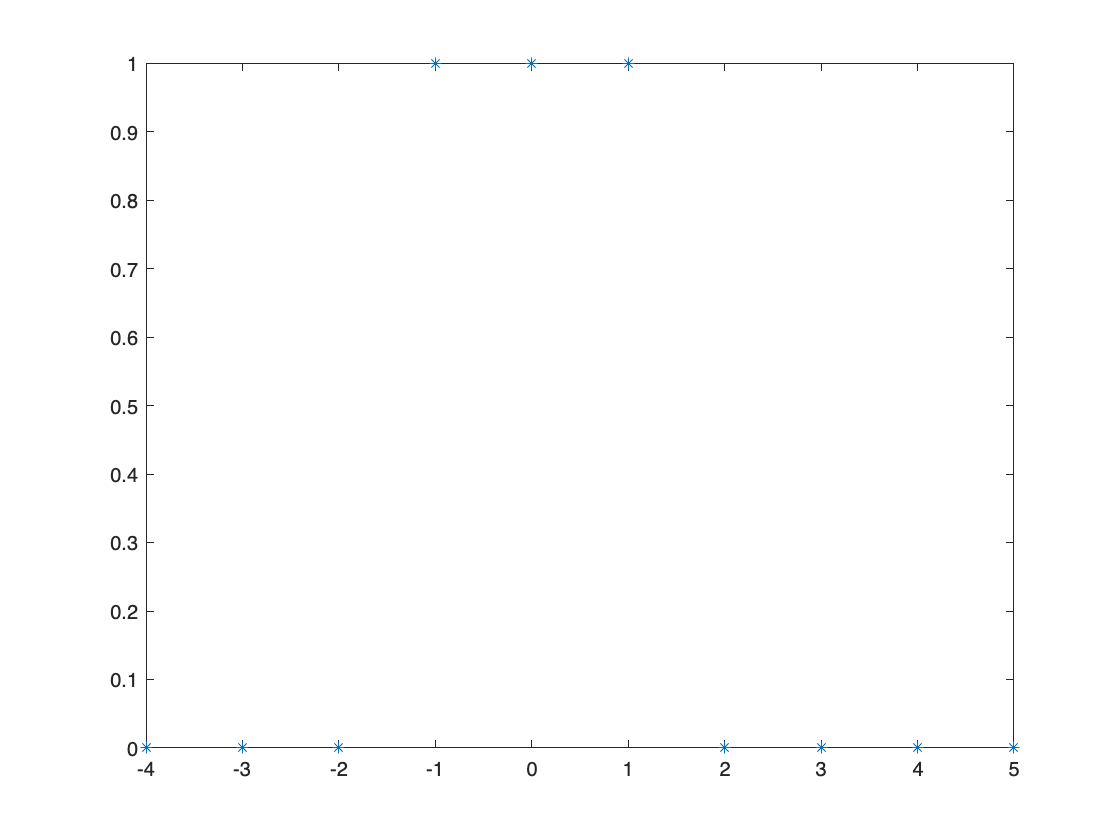

plot(x,y,'*')

- Del polinomi interpolador

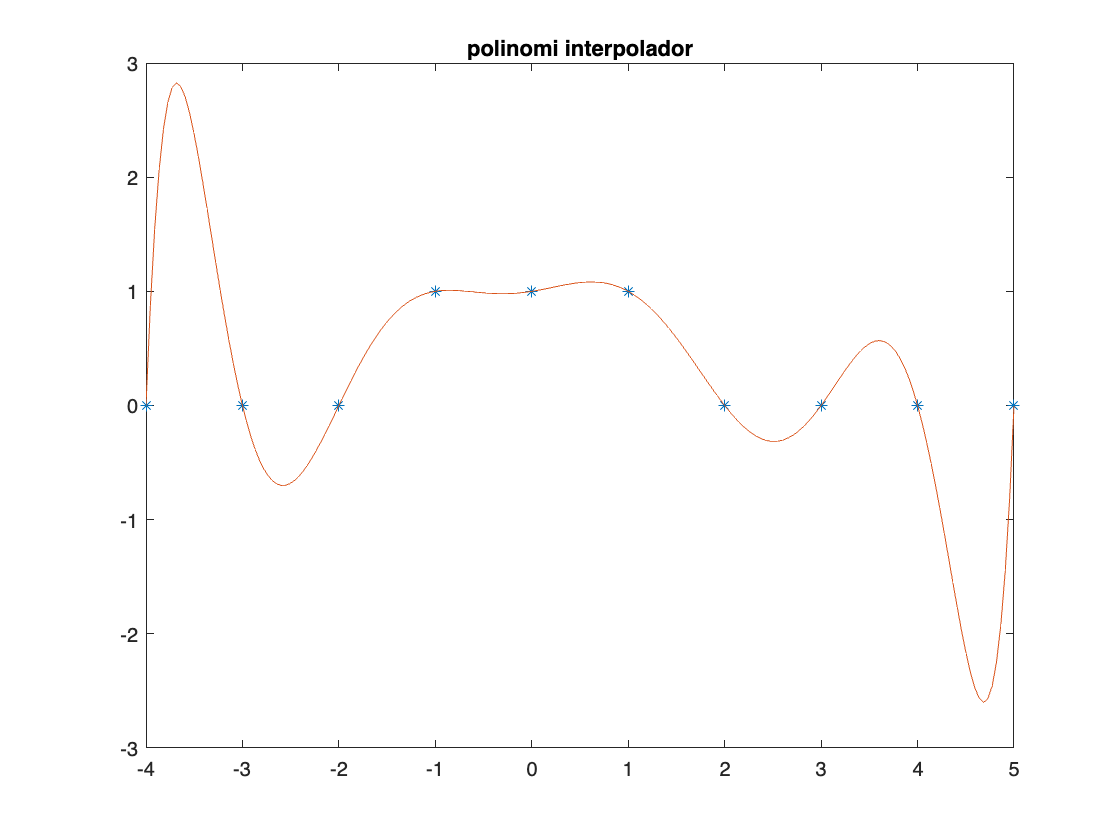

t = linspace(-4,5,200);
pt = polyinterp(x,y,t);
plot(x,y,'*',t,pt),title('polinomi interpolador'),axis([-4,5,-3,3])

- Del spline lineal

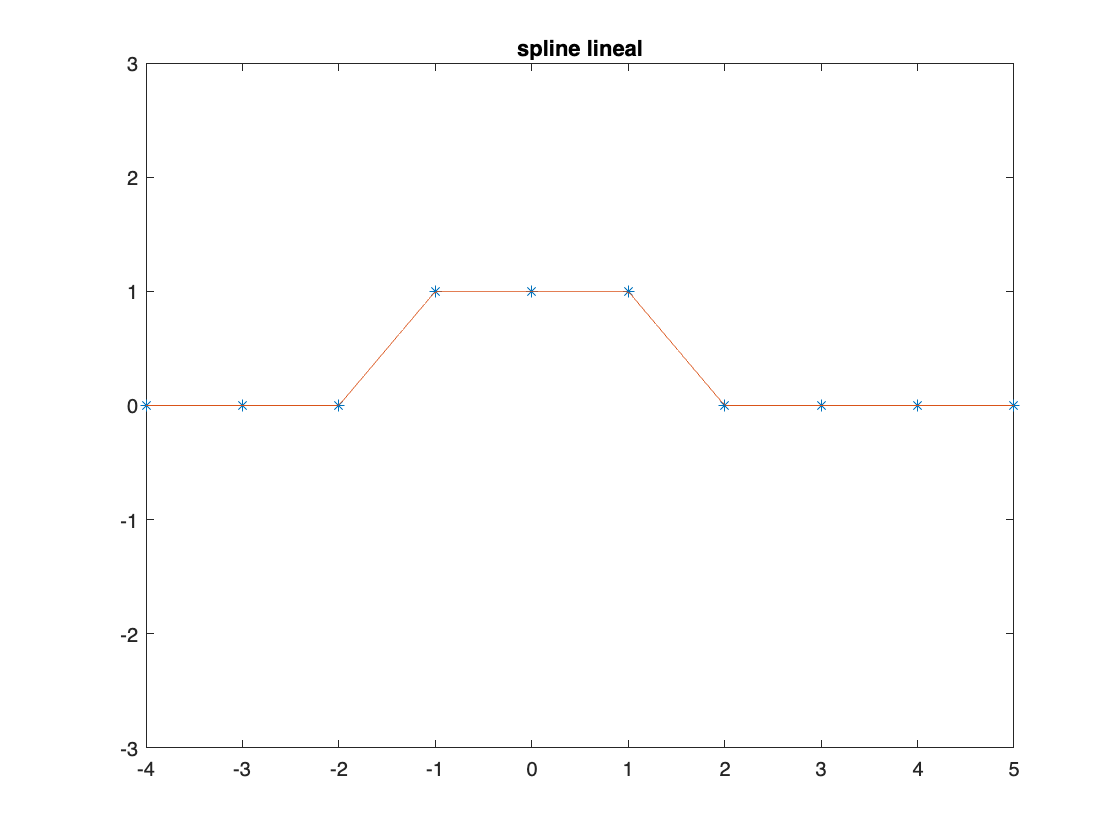

t = linspace(-4,5,200);
pt = interp1(x,y,t);
plot(x,y,'*',t,pt),title('spline lineal'),axis([-4,5,-3,3])

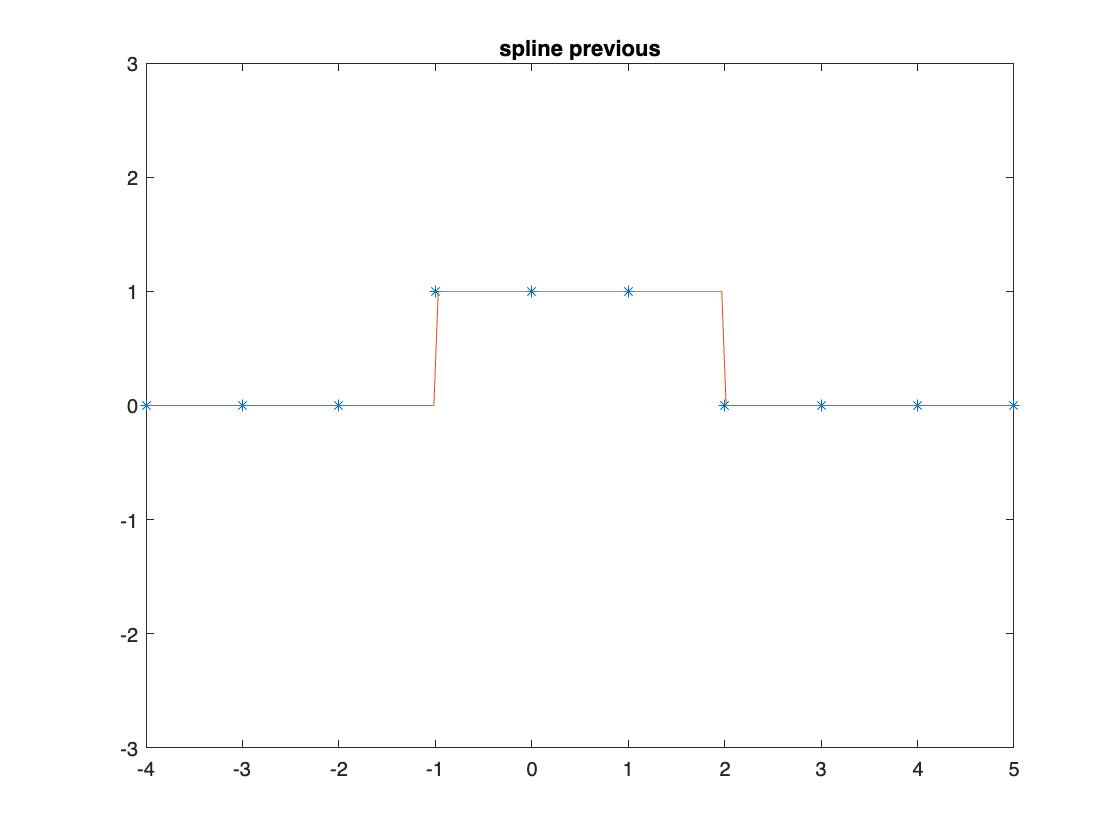

t = linspace(-4,5,200);
pt = interp1(x,y,t,'previous');
plot(x,y,'*',t,pt),title('spline previous'),axis([-4,5,-3,3])

- Del spline natural

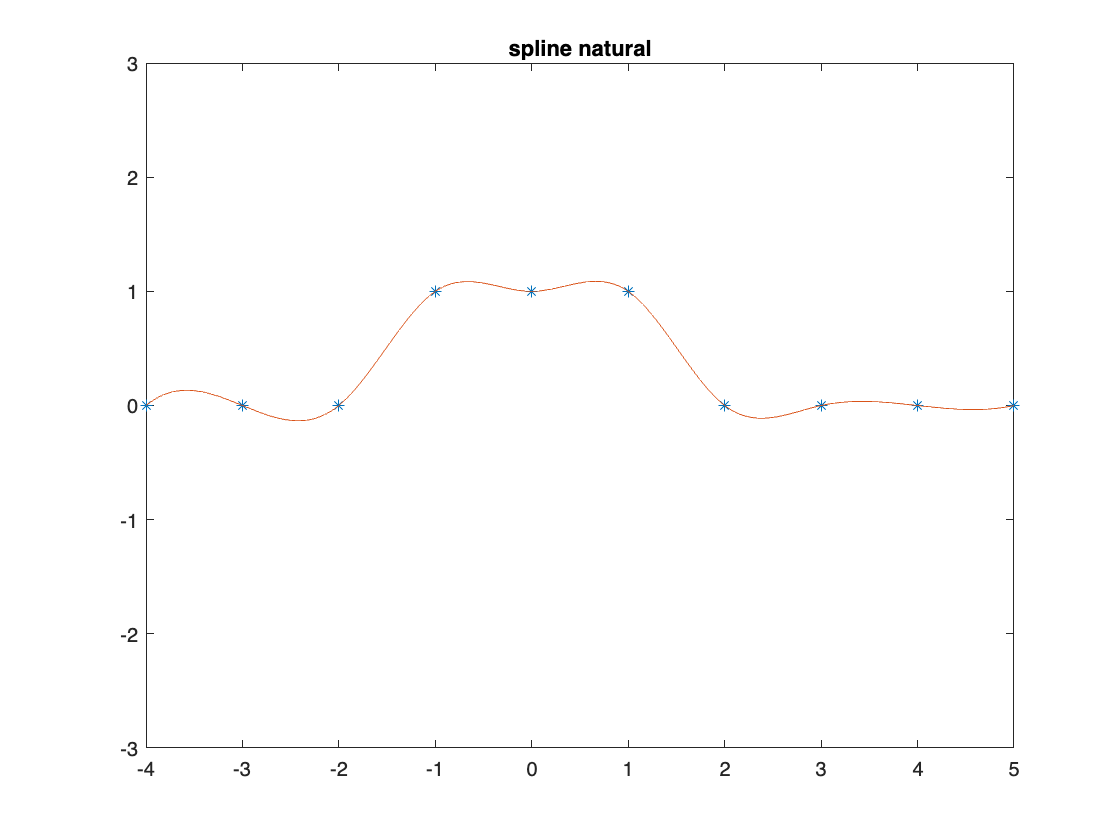

t = linspace(-4,5,200);
pt = interp1(x,y,t, 'spline');
plot(x,y,'*',t,pt),title('spline natural'),axis([-4,5,-3,3])

- Del spline shape-preserving

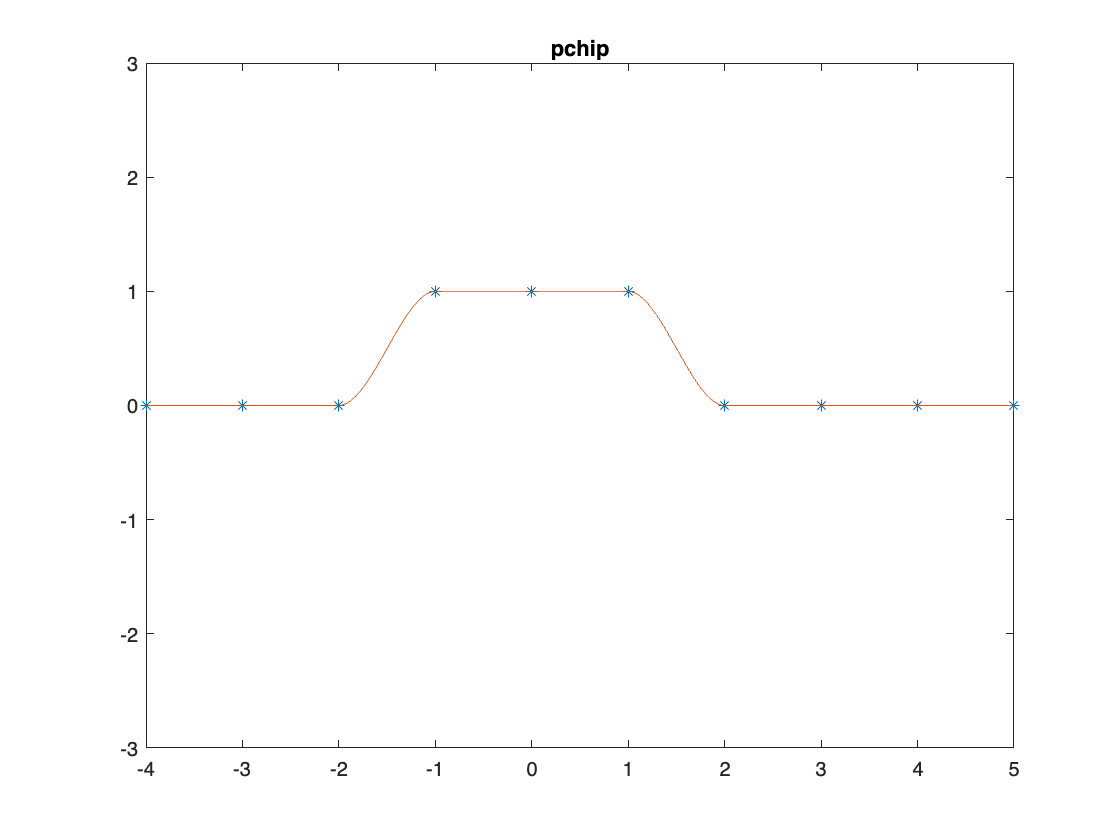

t = linspace(-4,5,200);
pt = interp1(x,y,t,'pchip');
plot(x,y,'*',t,pt),title('pchip'),axis([-4,5,-3,3])

### Exercici 7

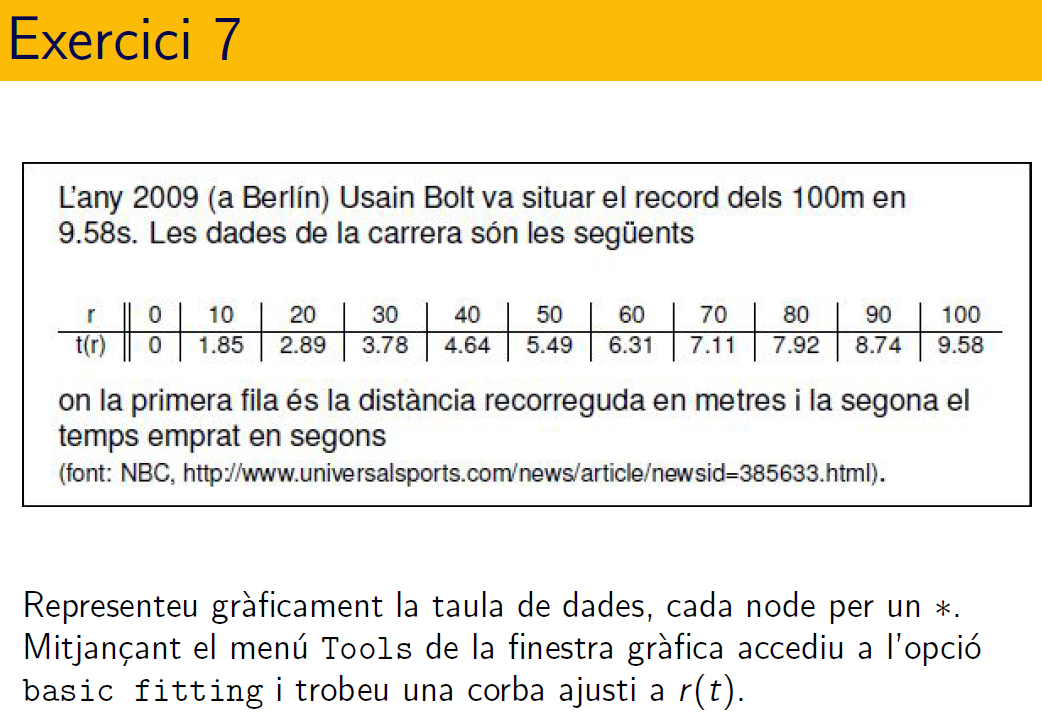

### Exercici 8

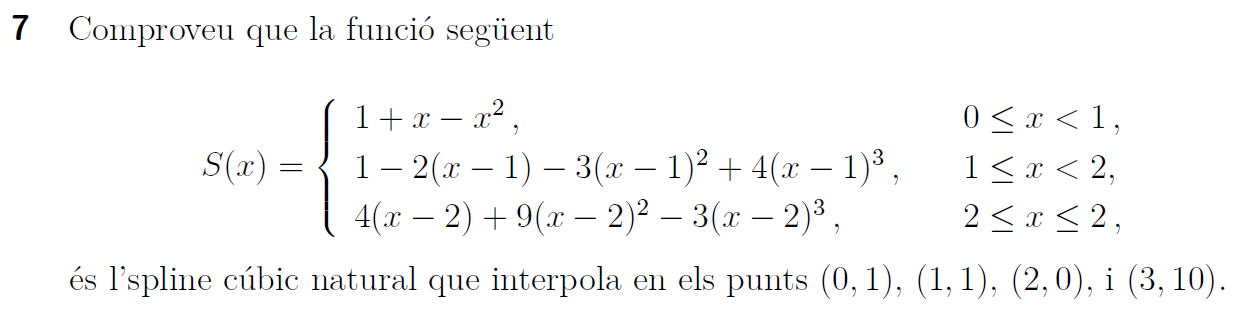

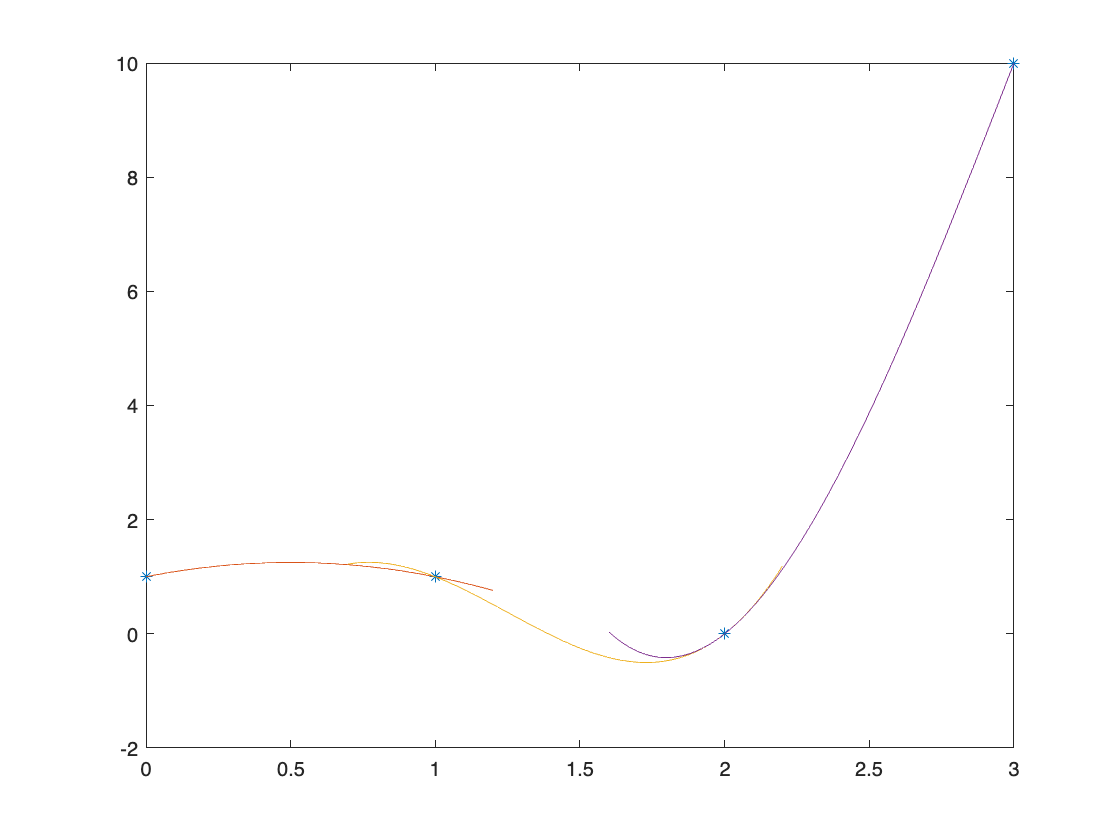

xn = [0 1 2 3]; yn = [1 1 0 10];
plot(xn,yn,'*')
hold on

s1 = @(x)1+x-x.^2;
t = linspace(0,1.2);
plot(t,s1(t));

s2 = @(x)1-2*(x-1)-3*(x-1).^2+4*(x-1).^3;
t = linspace(0.7,2.2);
plot(t,s2(t));


s3 = @(x)4*(x-2)+9*(x-2).^2-3*(x-2).^3;
t = linspace(1.6,3);
plot(t,s3(t));

hold off

## $\bullet$RECORDEM ... Bloc 3 

### Ajust de dades

### Funció de MATLAB®  

Els coeficients dels polinomis per mínims quadrats es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

openExample('matlab/FitPolynomialToSetOfPointsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 9

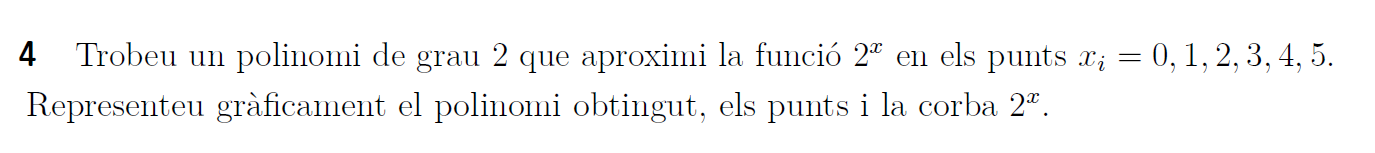

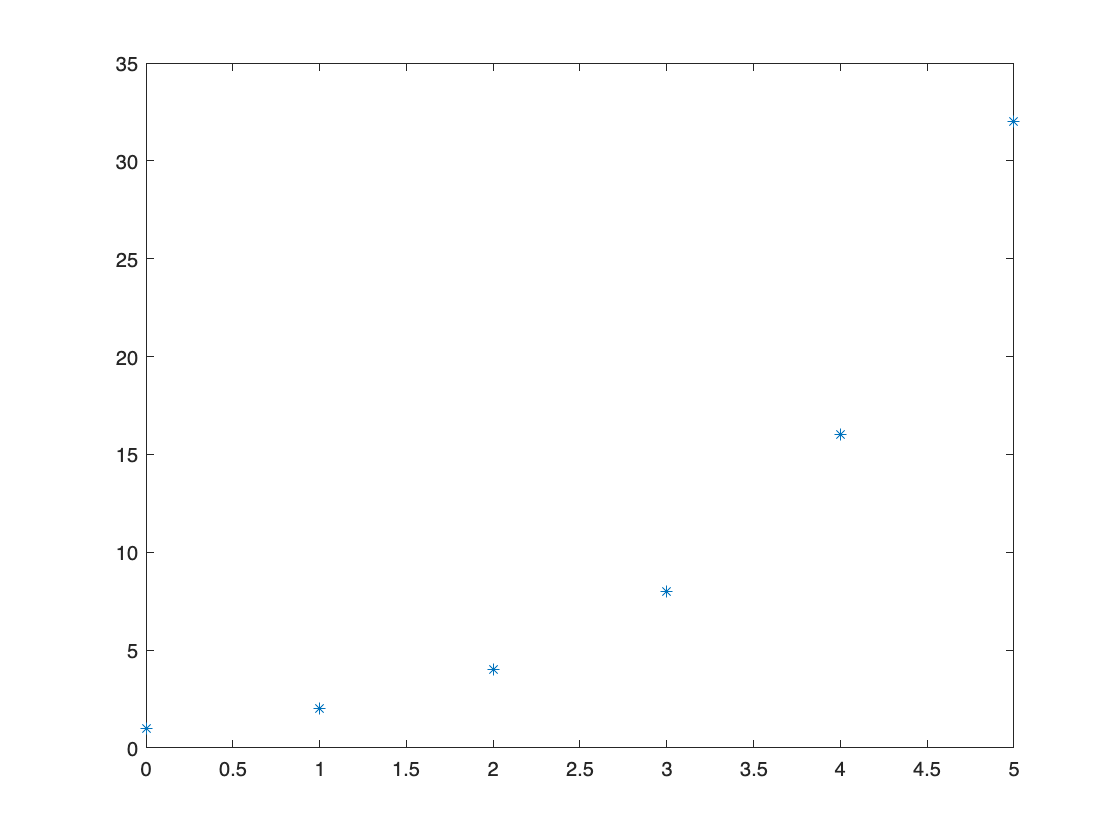

x = 0:5;
y = 2.^x;
plot(x,y,'*')

p = polyfit(x,y,2)

p =     1.7679   -3.0964    2.0357


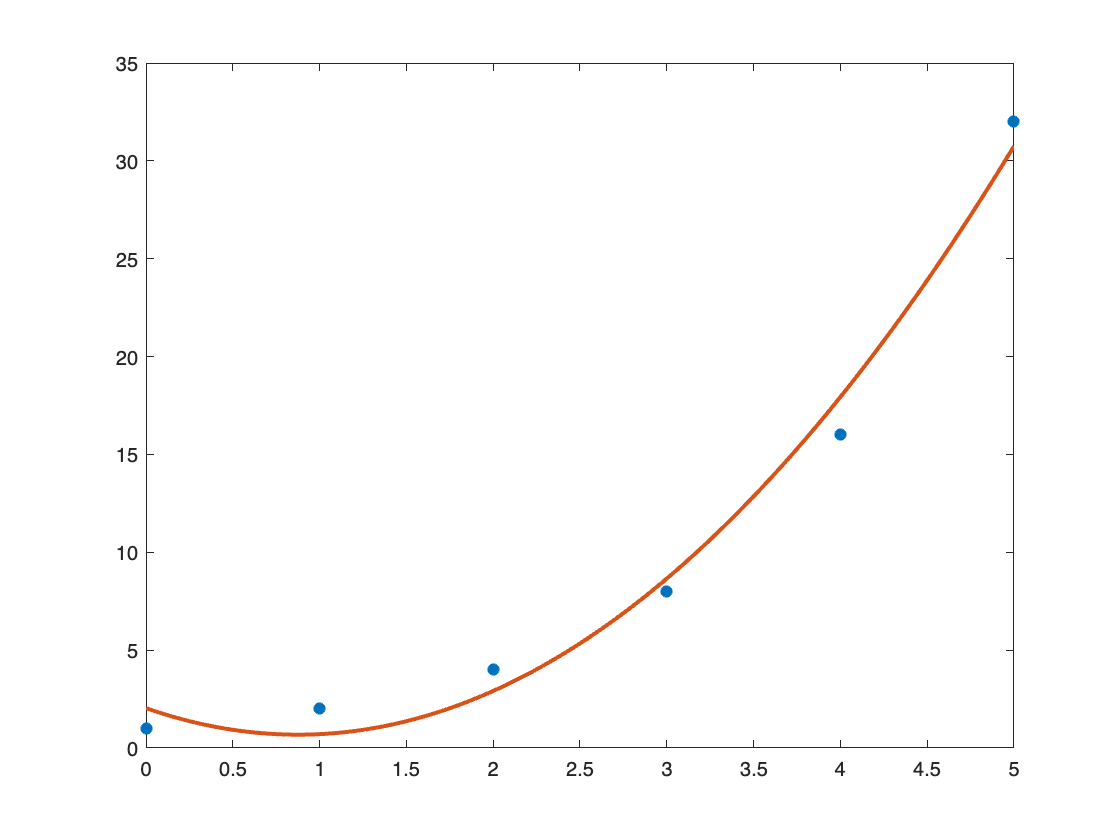

t = linspace(0,5);
pt = polyval(p,t);
plot(x,y,'*',t,pt,'LineWidth',2)

residu = norm(y - polyval(p,x))^2

residu = 9.6643

resultats = [y;polyval(p,x)]'

resultats =     1.0000    2.0357
    2.0000    0.7071
    4.0000    2.9143
    8.0000    8.6571
   16.0000   17.9357
   32.0000   30.7500


### Exercici 10.   

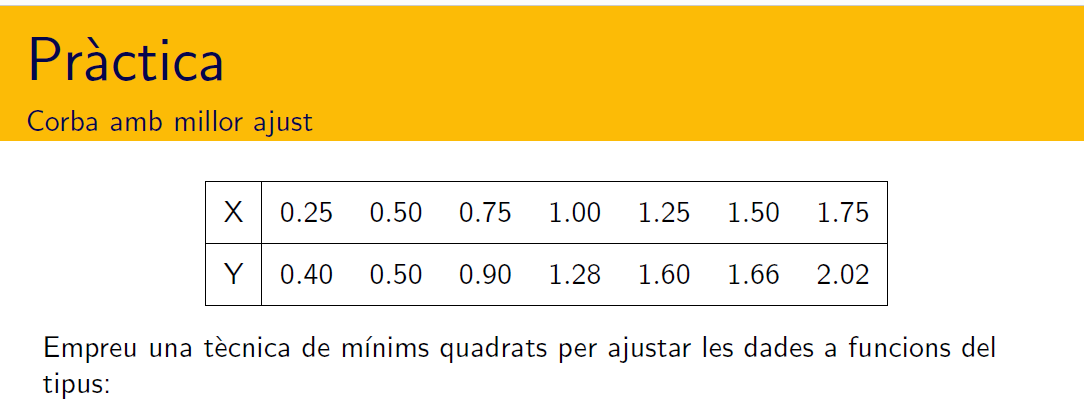

clearvars; clf; format shortG
x = 0.25:0.25:1.75;
y = [0.4,0.5 0.9 1.28 1.60 1.66 2.02];
disp([x;y]')

         0.25          0.4
          0.5          0.5
         0.75          0.9
            1         1.28
         1.25          1.6
          1.5         1.66
         1.75         2.02



- recta

p = polyfit(x, y, 1)

p =        1.1257     0.068571


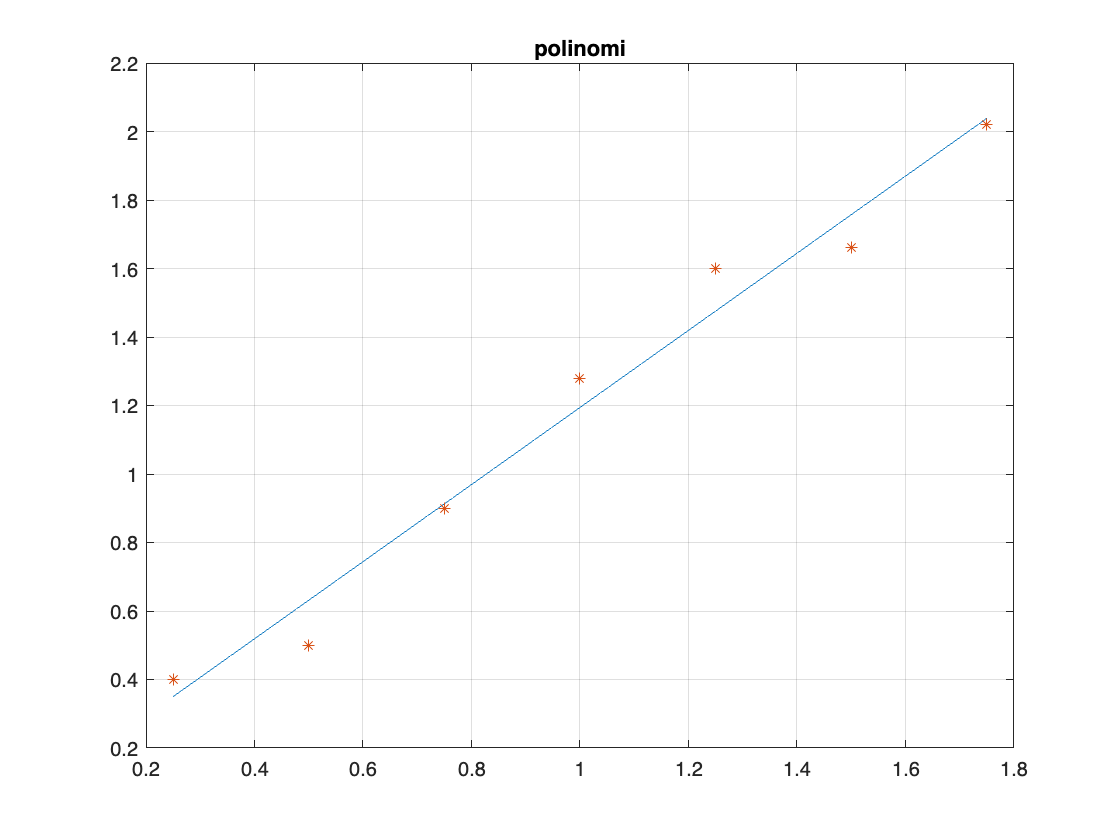

t = linspace(0.25, 1.75);
pt = polyval(p, t);
plot(t, pt, x, y, '*'), title('polinomi'), grid

- Polinomi de grau 4

p = polyfit(x, y, 4)

p =        2.2497      -9.4255       13.333      -6.0767       1.2286


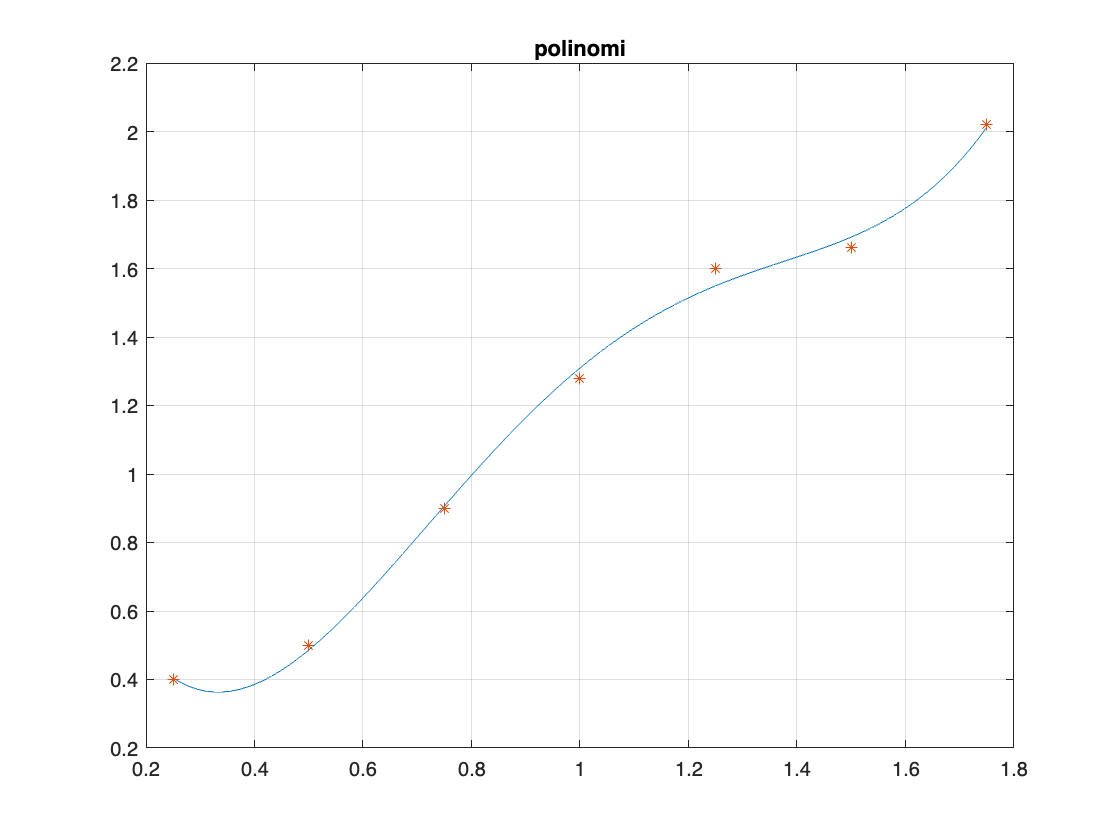

t = linspace(0.25, 1.75);
pt = polyval(p, t);
plot(t, pt, x, y, '*'), title('polinomi'), grid

- Corba $y = ax^{b}  \rightarrow \ln(y)=b\ln(x)+\ln(a) \rightarrow Y = A_1X+A_0$

p = polyfit(log(x), log(y), 1)

p =       0.89577      0.18114


p(2) = exp(p(2));
t = linspace(0.25, 1.75);
fx = p(2)*(t.^p(1))

fx =       0.34623      0.36497      0.38359      0.40212      0.42054      0.43887      0.45711      0.47527      0.49335      0.51135      0.52927      0.54713      0.56492      0.58264       0.6003       0.6179      0.63544      0.65293      0.67036      0.68774      0.70507      0.72235      0.73958      0.75676       0.7739        0.791      0.80805      0.82506      0.84203      0.85896      0.87585      0.89271      0.90952       0.9263      0.94305      0.95976      0.97644      0.99308       1.0097       1.0263       1.0428       1.0593       1.0758       1.0923       1.1087       1.1251       1.1415       1.1578       1.1742       1.1904


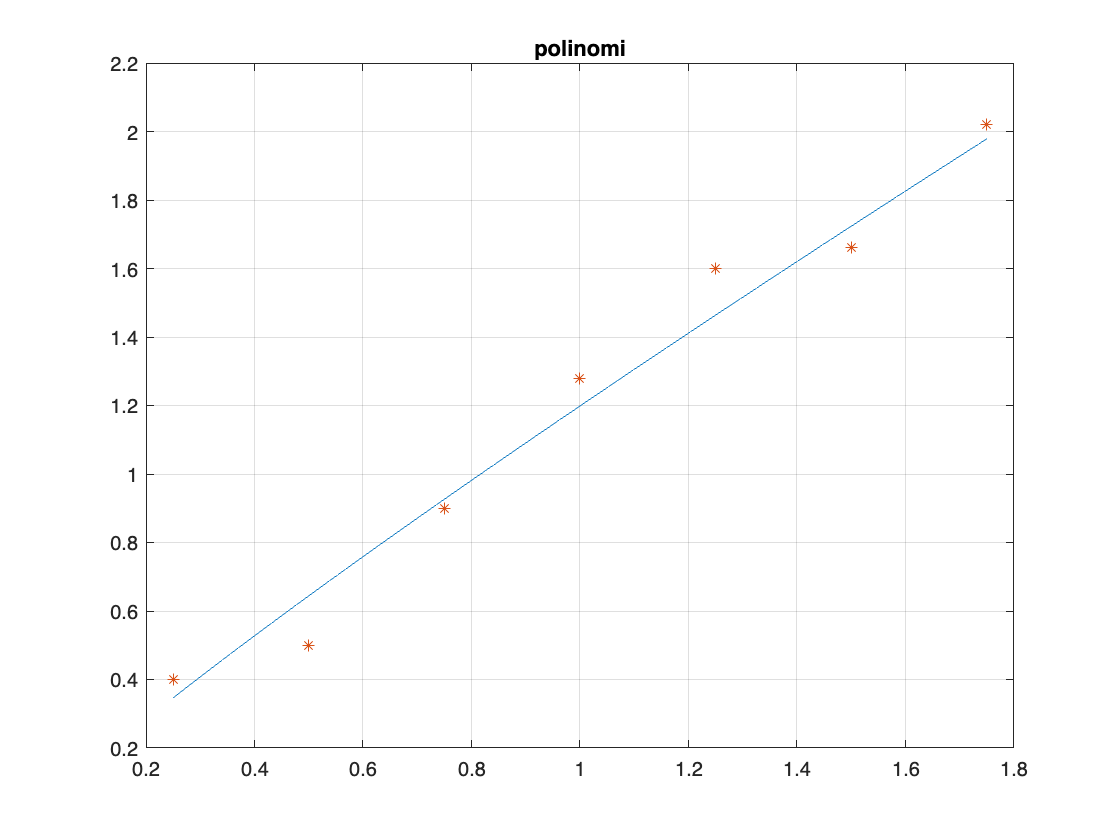

plot(t, fx, x, y, '*'), title('polinomi'), grid

- Gràfica

#### Exercici 11.  Sistema  sobredeterminat

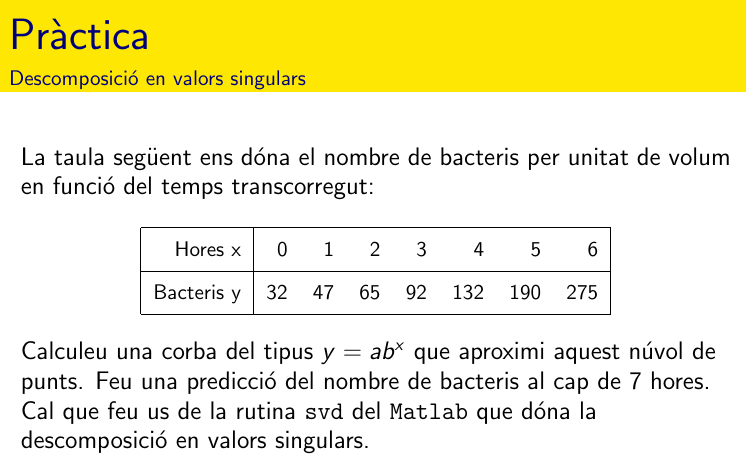

% veure practica5_exercici5

`document preparat per M. Àngela Grau Gotés - maig 2022`